close all;
clear variables;
NTTD = [2,4,8,16,32,64];
%%
%% (mW)
    PBB = 300; PRF = 200; 
    PTTD = 80; PPS = 20;
    PSW = 10; 
    PFTTD = 30; 
%% system parameters
Sysparam = struct();

Sysparam.Nt = 256;
Sysparam.Nr = 4;
Sysparam.Nrf=4;
Sysparam.Ns = 4;
Sysparam.fc = 300*1e9;%carrier frequency 
Sysparam.f = 30*1e9; %bandwidth 
Sysparam.K = 129;  %number of sub-carriers
Sysparam.L = 4 ; % number of paths equals to number of RF chains
Sysparam.tmax = 300e-12;% maximum time-delay value  
%% simulation parameters
Simparam = struct();

%Simparam.phi = pi*rand(Sysparam.L,1)-0.5*pi; %AoD;
Simparam.phi = pi*((0.5-0.2951)*rand(Sysparam.L,1)+0.2951) %AoD;

Simparam = struct with fields:
    phi: [4×1 double]


Simparam.psi = pi*rand(Sysparam.L,1)-0.5*pi; %AoA;

%Simparam.P = -20:5:15;% transmit power in dB
%Simparam.P = 10;% transmit power in dB
Simparam.Rho = 30; %transmit power (mW)
Simparam.Niter = 50; %channel realizations
%% Sub-carrier frequencies
for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 
%% 
%  H = WidebandChannel(Sysparam,Simparam);   
% [S,F2k,D,~] = DynamicSubarray(Sysparam,Simparam,H); %Dynamic subarray method
%% without beam squint compensation
for l = 1:Sysparam.L
    F3(:,l) = ArrResponseGenerateH(Sysparam.Nt,Simparam.phi(l),1)/sqrt(Sysparam.Nt);
end 
for n = 1:length(NTTD)
    %%
    Sysparam.M = NTTD(n); %number of TTDs for each RF chain
    Sysparam.N = Sysparam.Nt/Sysparam.M; %number of PSs for each TTD
    
    Sysparam.Q = NTTD(n); % number of fixed TTD element
    Sysparam.T = Sysparam.tmax*(0:1:Sysparam.Q-1)/(Sysparam.Q-1);
    %%
     P1(n) =  Simparam.Rho + PBB + Sysparam.Nrf*PRF + Sysparam.Nrf*Sysparam.M*PTTD + Sysparam.Nrf*Sysparam.Nt*PPS;
     P2(n) =  Simparam.Rho + PBB + Sysparam.Nrf*PRF + Sysparam.Nrf*Sysparam.M*PFTTD + Sysparam.Nt*PSW;
end

load RateComparison4.mat; %load the computed rate

%Compute the energy efficiency
for n = 1:length(NTTD)
    EE2(n) = Rate2(n)*1000/P1(n);
    EE3(n) = Rate3(n)*1000/P1(n);
    EE4(n) = Rate4(n)*1000/P2(n);
end

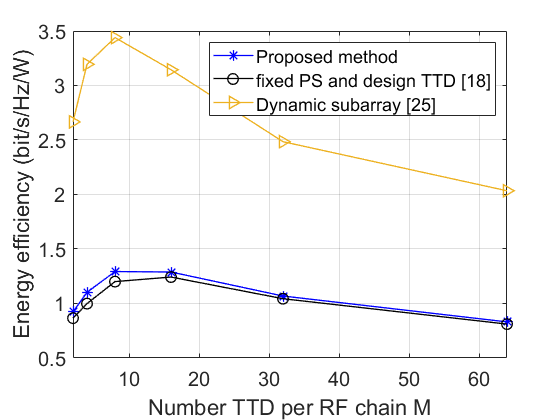

%%
set(0, 'defaultlinelinewidth', 1); set(0, 'defaultlinemarkersize', 8);
set(0, 'defaultaxesfontsize', 15); set(0, 'defaulttextfontsize', 15); 
%plot(NTTD,Rate1,'-r',NTTD,Rate2,'-*b',NTTD,Rate3,'-ok',NTTD,Rate4,'->',NTTD,Rate5,'-<')
plot(NTTD,EE2,'-*b',NTTD,EE3,'-ok',NTTD,EE4,'->')
grid on 
xlabel('Number TTD per RF chain M')
xlim([2,64])
ylabel('Energy efficiency (bit/s/Hz/W)')
legend('Proposed method','fixed PS and design TTD [18]','Dynamic subarray [25]')